[N,C,S] = normalize(lstmdata,"range")
a = S.*N+C
divide2=(0:250:2500)
divide1=(1:250:2500)

for i = 1:10
    datatrain{i}=N(divide1(i):divide2(i+1),:)'
end

for n = 1:numel(datatrain)
    X = datatrain{n};
    XTrain{n} = X(:,1:end-1);
    TTrain{n} = X(5:6,2:end); % lag XTrain 1 step
end

Model from Aj. Sompote (Keras)

% model = Sequential()
% model.add(LSTM(50, activation="relu", return_sequences=True, use_bias=True, input_shape=(X_data.shape[1], X_data.shape[2])))
% model.add(LSTM(25, activation="relu"))
% model.add(Flatten())
% model.add(Dense(25))
% #model.add(Flatten())
% model.add(Dense(2))
% model.add(Dense(Y_data.shape[1], activation="tanh"))
% 
% model.summary()

layers = [
    sequenceInputLayer(6)
    lstmLayer(128)
    fullyConnectedLayer(2)
    regressionLayer];

options = trainingOptions("adam", ...
    MaxEpochs=500, ...
    SequencePaddingDirection="left", ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=0);

net = trainNetwork(XTrain,TTrain,layers,options);

net = resetState(net);
offset = size(X,2);
[net,Z] = predictAndUpdateState(net,XTrain);

Open loop forecasting

YTest = predict(net,XTrain,SequencePaddingDirection="left");

first_timestep = [0; 0; 0; 0; 0; 0]

first_timestep =      0
     0
     0
     0
     0
     0



Y(:,1) = first_timestep(5:6,1)

Y =          0    0.2249    0.3264    0.3741    0.3968    0.4077    0.4130    0.4156    0.4168    0.4174    0.4177    0.4178    0.4179    0.4179    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180    0.4180
         0    0.0135    0.0080    0.0046    0.0028    0.0020    0.0016    0.0014    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0

x = first_timestep

x =      0
     0
     0
     0
     0
     0


for i = 1:249
    Y(:,i+1) = predictAndUpdateState(net,x);
    x = [0; 0; 0; 0; Y(1,i+1); Y(2,i+1)];
end

Unable to perform assignment because value of type 'SeriesNetwork' is not convertible to 'double'.

Caused by:
    Error using double
    Conversion to double from SeriesNetwork is not possible.

x = first_timestep

x =      0
     0
     0
     0
     0
     0


net = resetState(net);
offset = size(x,2);
[net,Z] = predictAndUpdateState(net,x);

numPredictionTimeSteps = 200;
Xt = [0; 0; 0; 0; Z(1,1); Z(2,1)];
Y = zeros(2,numPredictionTimeSteps);

for t = 1:numPredictionTimeSteps
    [net,Y(:,t)] = predictAndUpdateState(net,Xt);
    Xt = [0; 0; 0; 0; Y(1,t); Y(2,t)];
end

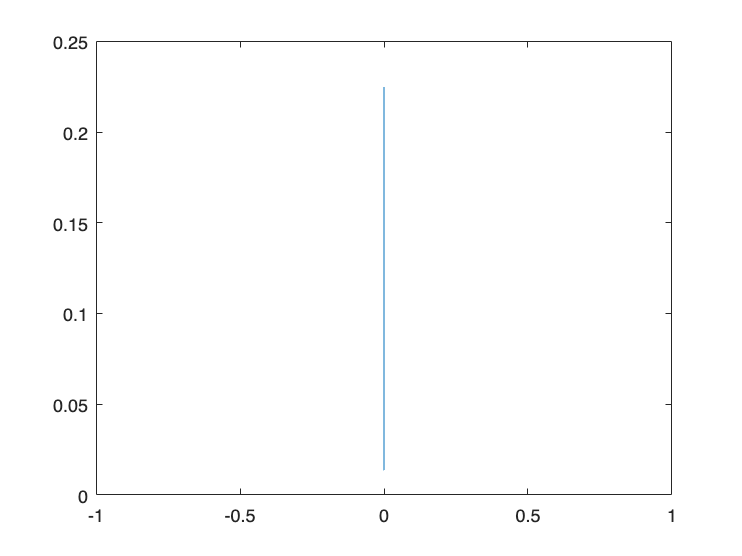

hold off;

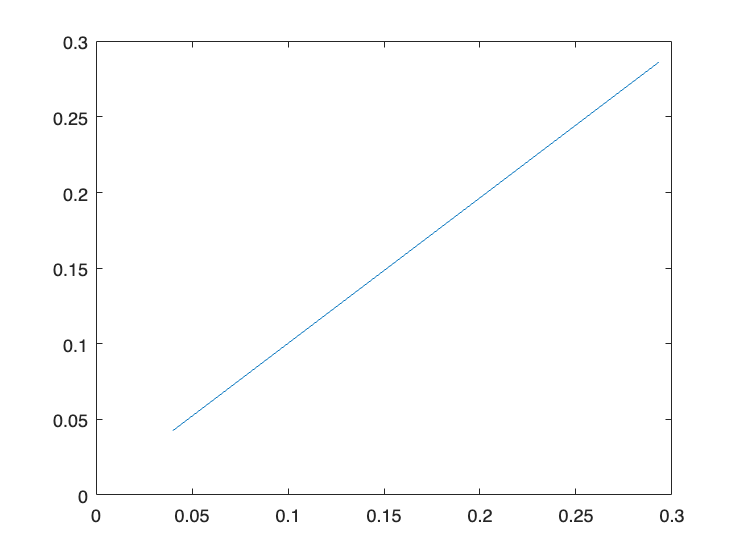

plot(Y(:,1),Y(:,2))

Test = YTest{3,1}
FEA = TTrain{1,3}
plot(Test(2,:),Test(1,:))
hold on;
plot(FEA(2,:),FEA(1,:))